
%m is the mass of the paratrooper
%g is the gravitational acceleration
%v(t)is the velocity of the paratrooper
%  cd is the drag constant
syms g m c_d
syms v(t)
eq = m*diff(v(t),t) + m*g == c_d*v(t)^2;
velocity = simplify(dsolve(eq, v(0) == 0));
u = symunit;
unitConversionFactor(u.N, u.kg*u.m/u.s^2)

$$ans = 1$$

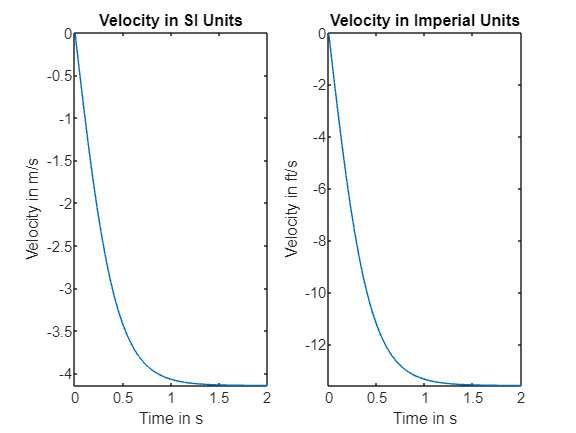

syms drag_units_SI
drag_units_SI = simplify(solve(drag_units_SI * (u.m / u.s)^2 == u.N));
% Mass of the paratrooper m = 70 kg
% Gravitational acceleration g = 9.81 m/s^2
%  Drag coefficient cd = 40 kg/m
% Substitute these values into the velocity equation and simplify the result.
vel_SI = subs(velocity,[g,m,c_d],[9.81*u.m/u.s^2, 70*u.kg, 40*drag_units_SI]);
vel_SI = simplify(vel_SI);
% Compute a numerical approximation of the velocity to 3 significant digits.
digits(3)
vel_SI = vpa(vel_SI);
vel_term_SI = limit(vel_SI, t, Inf);
%  convert the velocity function from SI units to imperial units.
vel_Imperial = rewrite(vel_SI,u.ft);
% Convert the terminal velocity
vel_term_Imperial = rewrite(vel_term_SI,u.ft);
% To plot the velocity as a function of time, express the time t in seconds and replace t by T s, where T is a dimensionless symbolic variable
syms T
vel_SI = subs(vel_SI, t, T*u.s);
% vel_SI = −4.14 tanh(2.37 T)*m/s
vel_Imperial = rewrite(vel_SI, u.ft);
% Separate the expression from the units by using separateUnits.
%  Plot the expression using fplot
% Convert the units to strings for use as plot labels by using symunit2str.
[data_SI, units_SI] = separateUnits(vel_SI);
[data_Imperial, units_Imperial] = separateUnits(vel_Imperial);
%The velocity of the paratrooper approaches steady state when t>1
subplot(1,2,1)
fplot(data_SI,[0 2])
title('Velocity in SI Units')
xlabel('Time in s')
ylabel(['Velocity in ' symunit2str(units_SI)])
subplot(1,2,2)
fplot(data_Imperial,[0 2])
title('Velocity in Imperial Units')
xlabel('Time in s')
ylabel(['Velocity in ' symunit2str(units_Imperial)])